M = 4;
k = log2(M);
nSymbols = 1000;
nBits = nSymbols*k;

SNRdB = 0:15;
nSNR = length(SNRdB);
SNR = 10.^(SNRdB/10);
noiseAmp = 1./SNR;

DBPSKsymMod = comm.DQPSKModulator;
DBPSKmod = comm.DQPSKModulator;
DBPSKdemod = comm.DQPSKDemodulator;

a = sqrt(2*SNR*(1-sqrt(1/2)));
b = sqrt(2*SNR*(1+sqrt(1/2)));
ThBER = marcumq(a,b) - 0.5*besseli(a.*b, 1).*exp(-0.5*(a.^2 + b.^2));

symbolSpace = (0:(M - 1))';
modSymSpace = DBPSKsymMod(symbolSpace);

nIter = 10;
totalSymbols = nIter*nSymbols;

SimSER = zeros(1, nSNR);

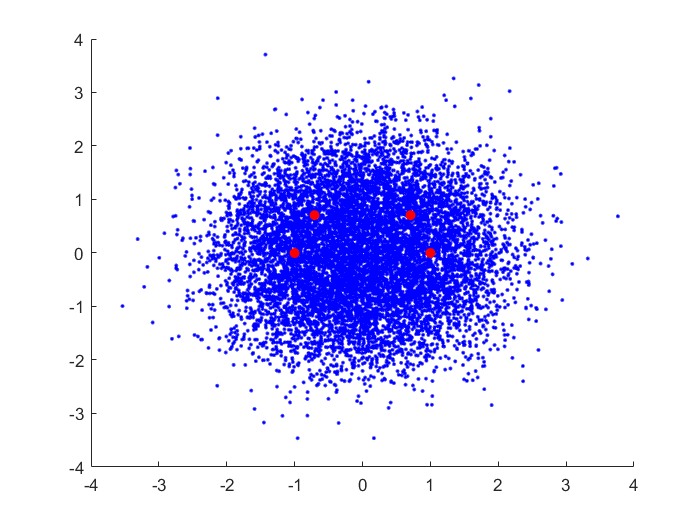

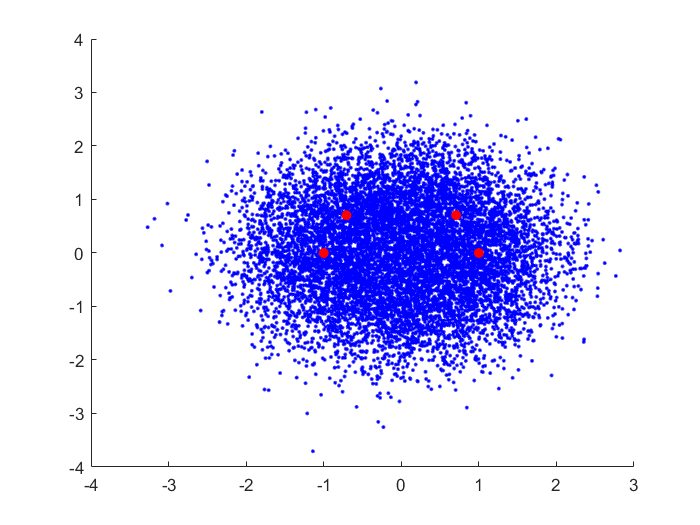

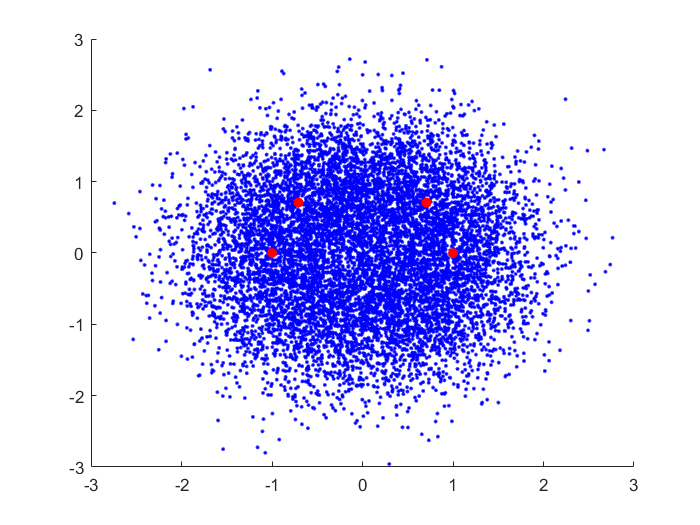

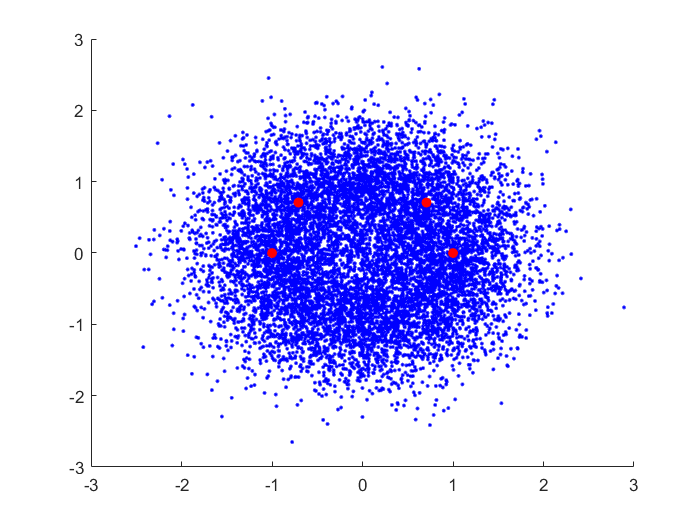

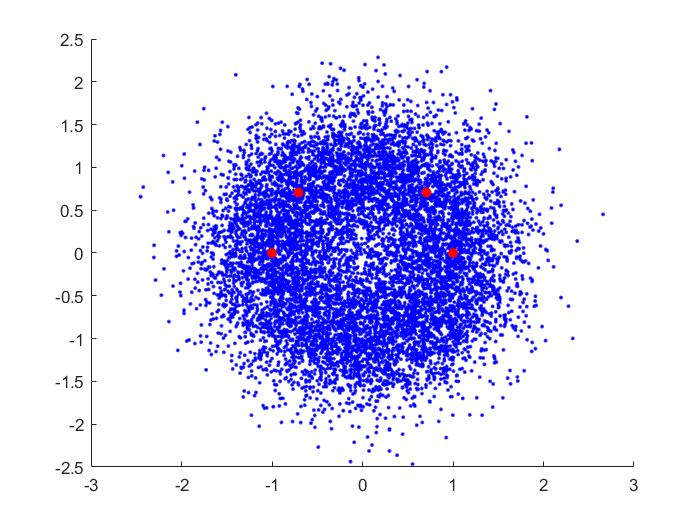

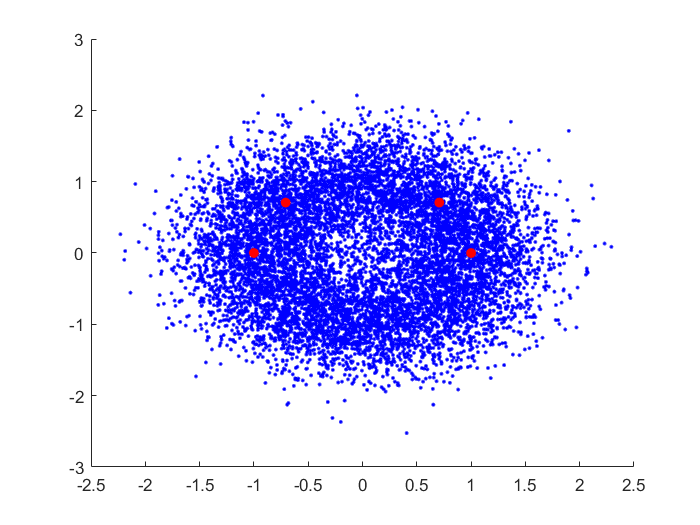

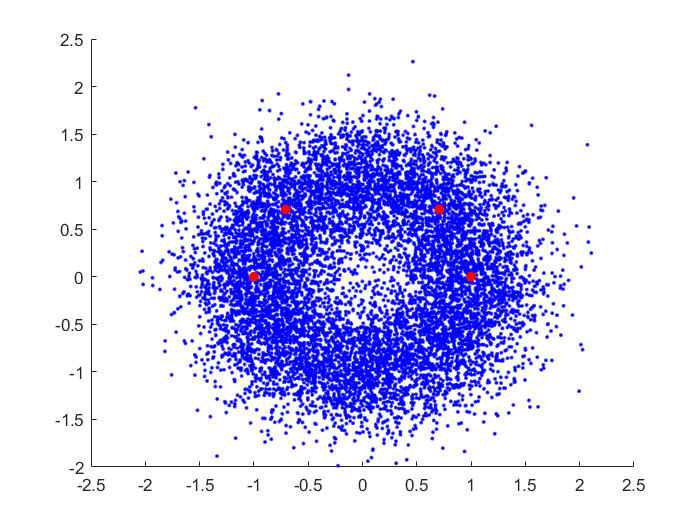

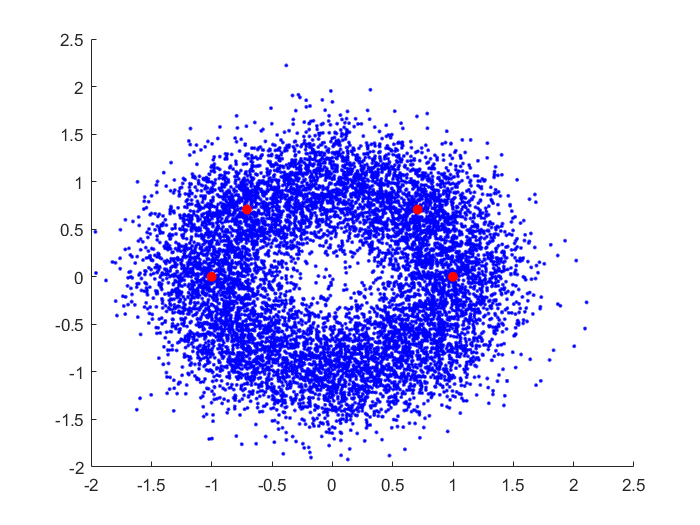

for SNRindex = 1:nSNR
    totalErrorSymbols = 0;
    channelSymbols = zeros(totalSymbols, 1);
    for iter = 1:nIter
        inBinSig = randi([0 1], nBits, 1);
        inBinMatrix = reshape(inBinSig, nSymbols, k);
        inSymSig = zeros(nSymbols, 1);
        for symIndex = 1:nSymbols
            inSymSig(symIndex) = polyval(inBinMatrix(symIndex, :), 2);
        end
        modSig = DBPSKmod(inSymSig);
        channelSig = modSig + sqrt(noiseAmp(SNRindex)/2)*randn(nSymbols, 1) + 1i*sqrt(noiseAmp(SNRindex)/2)*randn(nSymbols, 1);
        startIndex = 1 + (iter - 1)*nSymbols;
        endIndex = iter*nSymbols;
        channelSymbols(startIndex:endIndex) = channelSig;
        demodSymSig = DBPSKdemod(channelSig);
        totalErrorSymbols = totalErrorSymbols + sum(demodSymSig ~= inSymSig);
    end
    SimSER(SNRindex) = totalErrorSymbols/totalSymbols;
    figure(SNRindex);
    scatter(real(channelSymbols), imag(channelSymbols), 'b.');
    hold on;
    scatter(real(modSymSpace), imag(modSymSpace), 'red', 'filled');
    hold off;
end

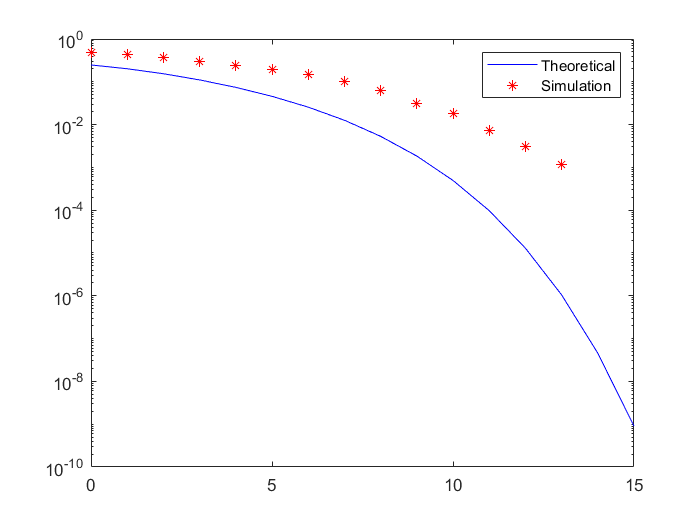

figure(SNRindex+1);
semilogy(SNRdB, ThBER, 'blue');
hold on;
semilogy(SNRdB, SimSER, 'r*');
hold off;
legend('Theoretical', 'Simulation');